# Esperimenti Equilibrio

clc
clear
close all

set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');

load("modello\data.mat");
warning("off" , "all");
load_system("modello\model.mdl");

N = length(time);
Ts = time(2) - time(1);

## Simulazione con i valori dati:

sim("model");

i = 1

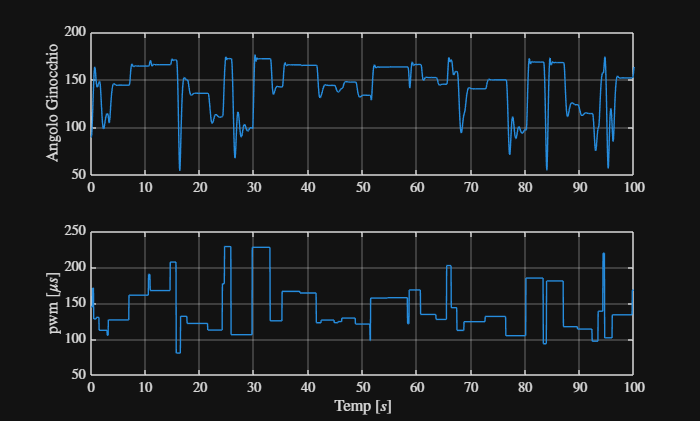

figure;
subplot(2 , 1 ,1);
plot(time , y);
ylabel("Angolo Ginocchio")
grid on;
subplot(2 , 1 , 2);
plot(time , u);
ylabel("pwm $[\mu s]$");
xlabel("Temp $[s]$");
grid on;

## Testiamo il se con diverse intensità

Sembra che per pw al di sotto dei $100\mu 
s$ non succede nulla (o quasi) mentre se si superano iniziamo a muovere il ginocchio:

pw = [zeros(201,1); 25 * ones(200 , 1) ; 50 * ones(200 , 1);
75* ones(200 , 1);100 * ones(200 , 1); linspace(100 , 120 , 200)';
120*ones(800 , 1)];
sim("model");

i = 1

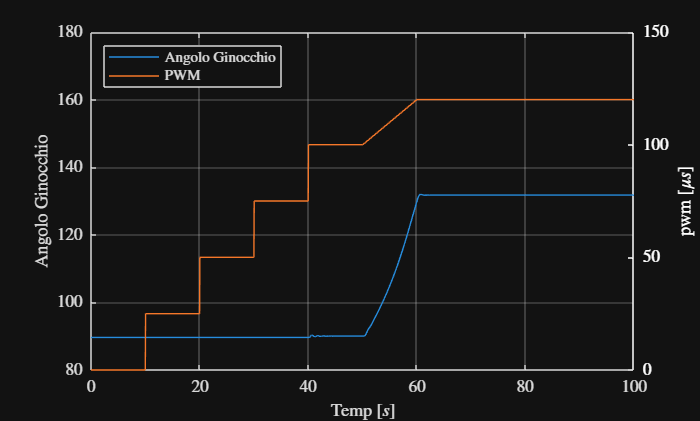

figure;
plot(time , y , DisplayName="Angolo Ginocchio");
ylim([80 180]);
ylabel("Angolo Ginocchio")
yyaxis right;
plot(time , u , DisplayName="PWM");
ax = gca;
ax.YColor = "w";
ylim([0 150]);
ylabel("pwm $[\mu s]$");
xlabel("Temp $[s]$");
yyaxis left;
legend();

grid on

legend(Location="northwest");

## Vogliamo un punto di equliblio a $135\degree $

Si ha che  per i $135\degree $ il pwm è di circa $121.35 \mu s$ infatti dando uno scalino si ha:

pw_eq = 121.35;

pw = [zeros(10/Ts , 1) ;            % 10 secondi a 0
        pw_eq * ones(20/Ts , 1);    % 20 secondi a 116.5
        zeros(70/Ts +1 , 1)];
sim("model");

i = 1

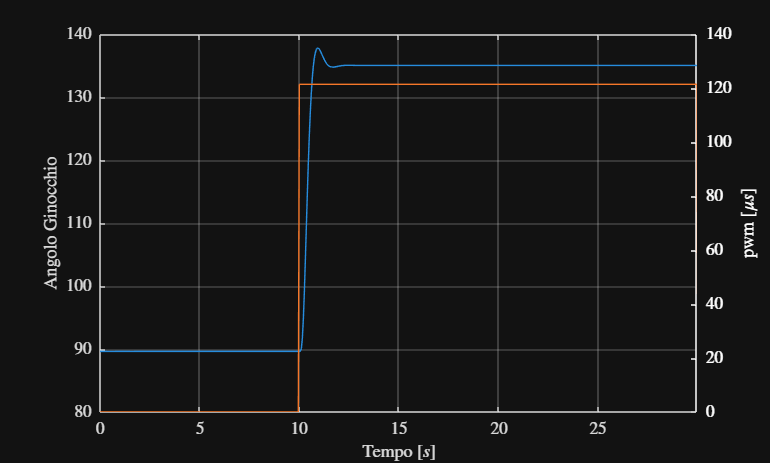

figure;
plot(time , y);
ylabel("Angolo Ginocchio");
grid on;
yyaxis("right");
ax = gca;
ax.YColor = "w";
plot(time , u);
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")
xlim([0 30-Ts]);
yyaxis("left");

Oservando l'angolo del ginocchio osserviamo che c'è un ritardo di circa $5 /10\mu s$ che corrsipondono a $1/2 $passi:

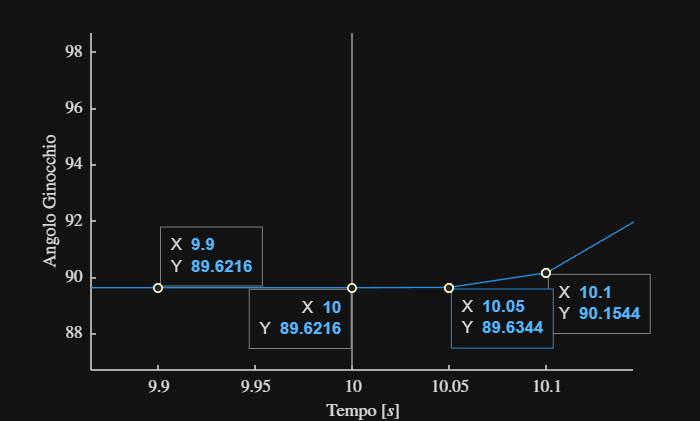

figure;
indice_inizio = floor(9.95/Ts);
indice_fine = floor(10.5/Ts);
intervallo = indice_inizio:indice_fine;
y_zoom = y(intervallo);
passo_1 = 202;
passo_2 = 203;
time_zoom = time(intervallo);
hold on
plot(time_zoom , y_zoom);
plot(time(passo_1) , y(passo_1) , Marker="x" , LineWidth=3);
plot(time(passo_2) , y(passo_2) , Marker="x" , LineWidth=3);
xline(10)
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
hold off;

xlim([9.865 10.145])
ylim([86.7 98.7])
 
ax2 = gca;
chart = ax2.Children(2);
datatip(chart,10.1,89.95,"Location","southeast");
chart = ax2.Children(4);
datatip(chart,10,89.62,"Location","southwest");
datatip(chart,9.9,89.62,"Location","northeast");
chart = ax2.Children(3);
datatip(chart,10.05,89.63,"Location","southeast");

Si vuole controllare l'angolo con $\pm 10\degree $ quindi $145\degree $ e $125\degree $, creaiamo 4 segnali diversi per l'input:

- Randomico tra 117.5 e 127.1

- Sinusoidale costante sempre tra 117.5 e 127.1

- Prendendo l'ingresso fornito e riscalando nel range 117.5 - 127.1

- Creando un rumore bianco tra 117.5 e 127.1

% Primo metodo
pw_max = 127.1;
pw_min = 117.5;

load("pw_1.mat");

pw = pw_1;
sim("model");

i = 1

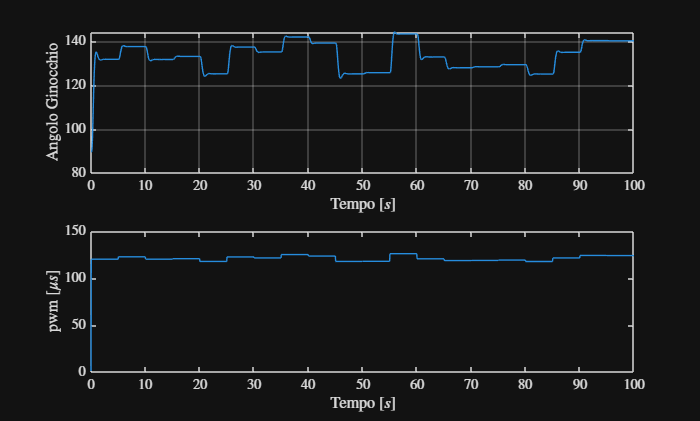

y_1 = y; 
figure;
subplot(2 , 1 , 1);
plot(time , y);
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
grid on;
subplot(2 , 1 , 2);
plot(time , u);
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")

% Secondo metodo

f=10; % [1/s]
A = (pw_max - pw_min)/2;
C = (pw_max + pw_min)/2;

pw_2 = A*sin(time) + C;

pw = pw_2;

sim("model");

i = 1

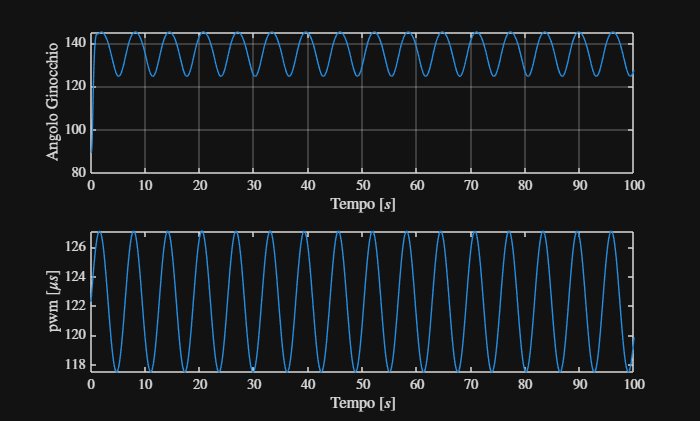

y_2 = y;
figure;
subplot(2 , 1 , 1);
plot(time , y);
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
grid on;
subplot(2 , 1 , 2);
plot(time , u);
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")

%terzo metodo
load("modello\data.mat");
pw_min_dato = min(pw);
pw_max_dato = max(pw);

pw_3 = pw_min + (pw - pw_min_dato)/(pw_max_dato - pw_min_dato)*(pw_max - pw_min);
pw = pw_3;
sim("model");

i = 1

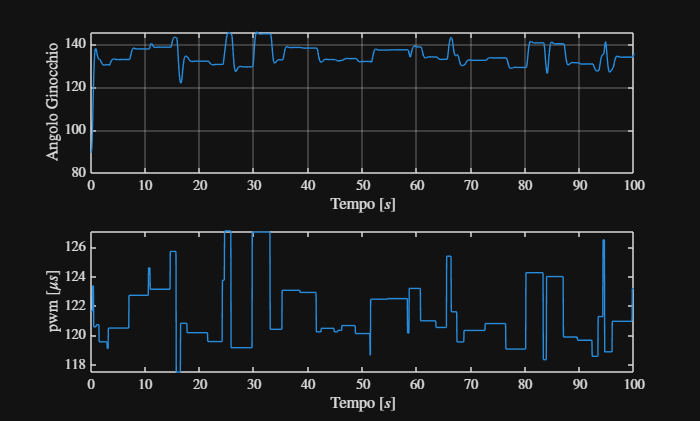

y_3 = y;
figure;
subplot(2 , 1 , 1);
plot(time , y);
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
grid on;
subplot(2 , 1 , 2);
plot(time , u);
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")


% Quarto metodo
% pw_4 = [];
% while length(pw_4) <= N
% 
%     max_s = 5;
%     min_s = 0.5;
%     elementi = rand(1 , 1) * (max_s/Ts  - min_s/Ts)  + min_s/Ts ;
%     pw_4 = [pw_4 ; rand(1 , 1) * ones(floor(elementi) , 1) * (pw_max  - pw_min)  + pw_min];
% end
% 
% pw_4 = pw_4(1:N);
load("pw_4.mat");
pw = pw_4;
sim("model");

i = 1

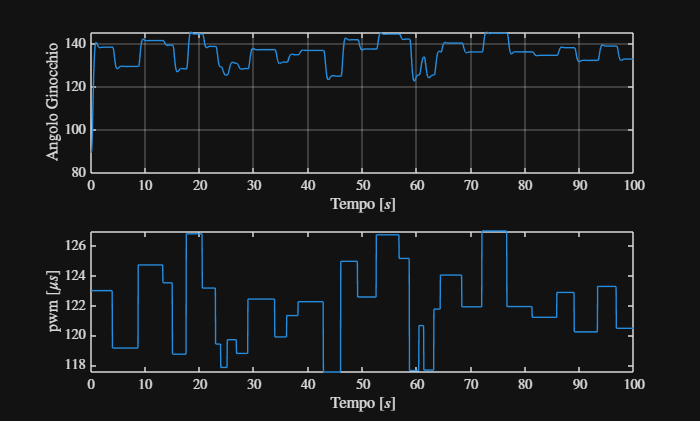

y_4 = y;
figure;
subplot(2 , 1 , 1);
plot(time , y);
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
grid on;
subplot(2 , 1 , 2);
plot(time , u);
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")

## Identificazione del modello utilizzando il segnale del primo metodo

dividiamo in 70% e 30% per la validazione

% 70% dei dati
n_70 = floor(N*0.7);
y_modello = y_1(1:n_70);
u_modello = pw_1(1:n_70);


data = iddata(y_modello , u_modello , Ts);

%definizione ordini AR MA X e K
n_ar = 5;
n_ma = 1;
n_x = 3;
k = 2;

%Sima del modello
modello_armax = armax(data , [n_ar n_x n_ma k])


modello_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                   
  A(z) = 1 - 3.444 z^-1 + 4.654 z^-2 - 3.094 z^-3 + 1.024 z^-4 - 0.1404 z^-5
                                                                            
  B(z) = 0.02228 z^-2 + 0.009192 z^-3 - 0.03145 z^-4                        
                                                                            
  C(z) = 1 + 0.5982 z^-1                                                    
                                                                            
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=3   nc=1   nk=2
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 99.98% (prediction focus)
FPE: 2.469e-06, MSE: 2.42e-06                    
 


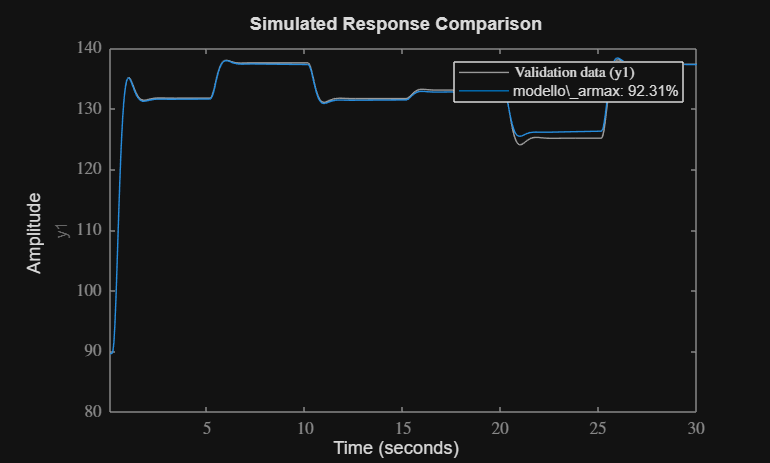

% Validazione con il 30% del primo set
n_30 = N - n_70;

y_val = y_1(1:n_30);
u_val = pw_1(1:n_30);

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

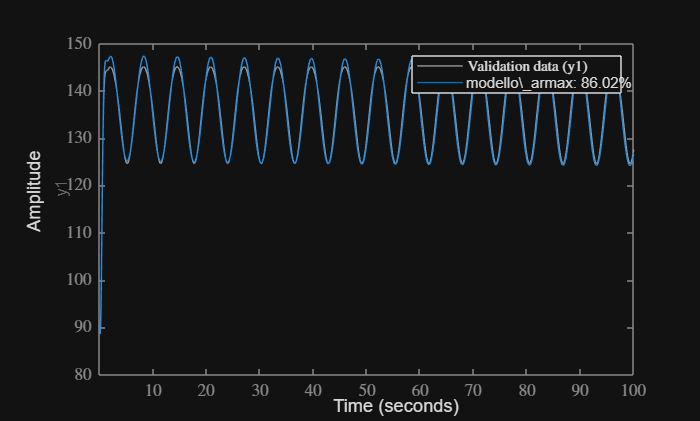

% Validazione con secondo set
y_val = y_2;
u_val = pw_2;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

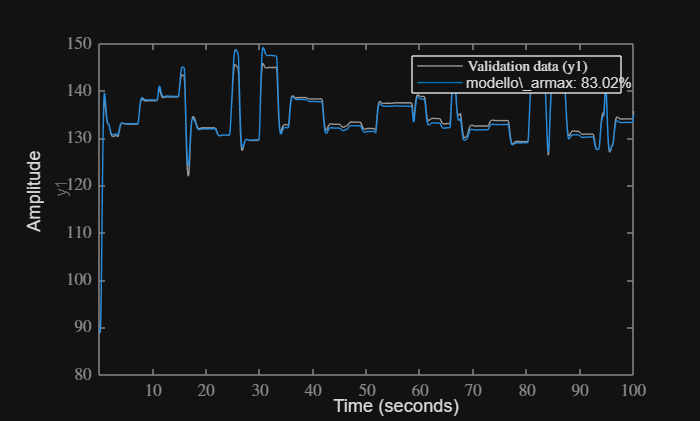

% Validazione con il terzo set
y_val = y_3;
u_val = pw_3;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

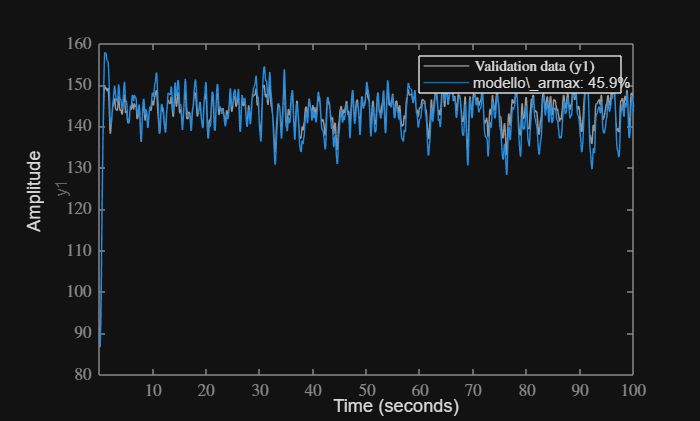

% Validazione con il quarto set
y_val = y_4;
u_val = pw_4;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

## Identificazione del modello utilizzando il segnale del secondo metodo

dividiamo in 70% e 30% per la validazione (è instabile)

% 70% dei dati
n_70 = floor(N*0.7);
y_modello = y_2(1:n_70);
u_modello = pw_2(1:n_70);


data = iddata(y_modello , u_modello , Ts);

%definizione ordini AR MA X e K
n_ar = 3;
n_ma = 1;
n_x = 3;
k = 2;

%Sima del modello
modello_armax = armax(data , [n_ar n_x n_ma k])


modello_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.884 z^-1 + 2.794 z^-2 - 0.9132 z^-3       
                                                         
  B(z) = 0.1008 z^-2 - 0.0933 z^-3 - 0.01127 z^-4        
                                                         
  C(z) = 1 + 0.2328 z^-1                                 
                                                         
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=1   nk=2
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 99.72% (prediction focus)
FPE: 0.0004777, MSE: 0.0004709                   
 


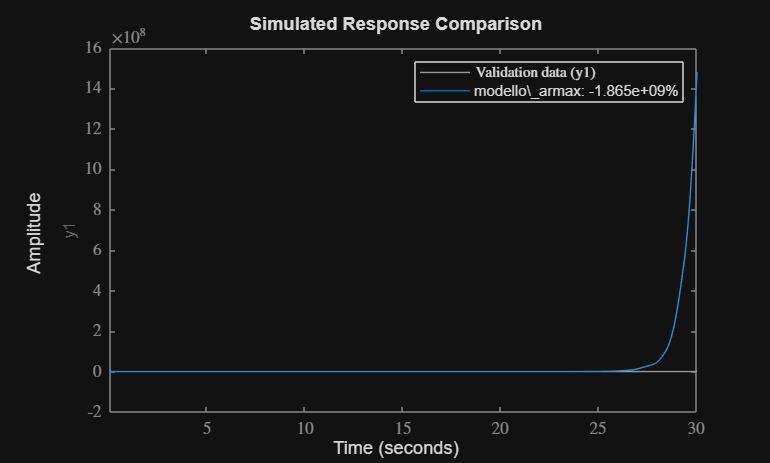

% Validazione con il 30% del secondo set
n_30 = N - n_70;

y_val = y_2(1:n_30);
u_val = pw_2(1:n_30);

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

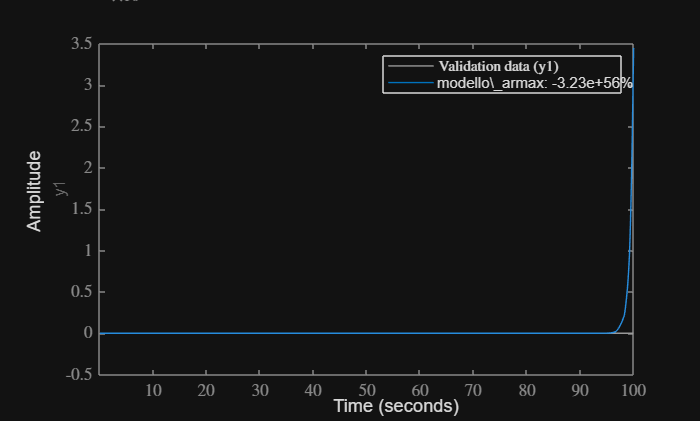

% Validazione con il primo set
y_val = y_1;
u_val = pw_1;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

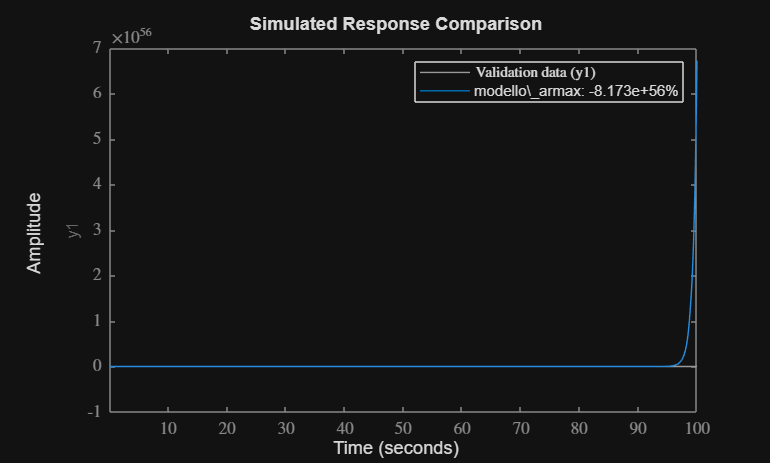

% Validazione con il terzo set
y_val = y_3;
u_val = pw_3;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

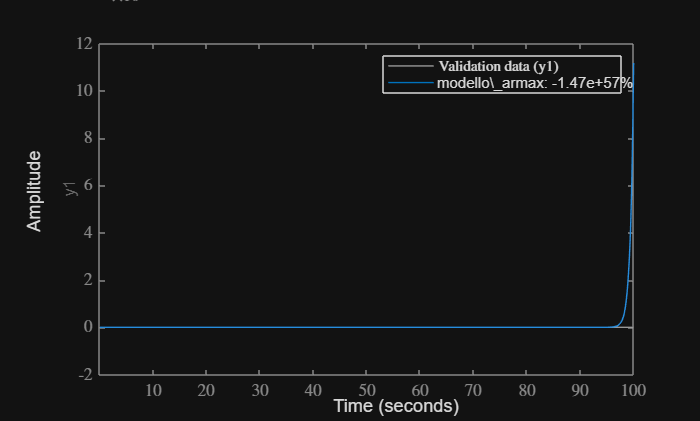

% Validazione con il quarto set
y_val = y_4;
u_val = pw_4;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

## Identificazione del modello utilizzando il segnale del terzo metodo

dividiamo in 70% e 30% per la validazione 

% 70% dei dati
n_70 = floor(N*0.7);
y_modello = y_3(1:n_70);
u_modello = pw_3(1:n_70);


data = iddata(y_modello , u_modello , Ts);

%definizione ordini AR MA X e K
n_ar = 5;
n_ma = 1;
n_x = 4;
k = 2;

%Sima del modello
modello_armax = armax(data , [n_ar n_x n_ma k])


modello_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                     
  A(z) = 1 - 3.261 z^-1 + 4.065 z^-2 - 2.382 z^-3 + 0.6391 z^-4 - 0.06175 z^-5
                                                                              
  B(z) = 0.02189 z^-2 + 0.01387 z^-3 - 0.03064 z^-4 - 0.005156 z^-5           
                                                                              
  C(z) = 1 + 0.8012 z^-1                                                      
                                                                              
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=4   nc=1   nk=2
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 99.96% (prediction focus)
FPE: 4.99e-06, MSE: 4.884e-06                    
 


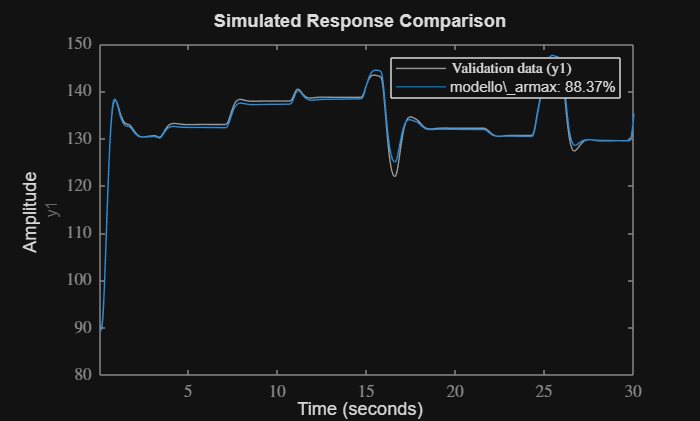

% Validazione con il 30% del terzo set
n_30 = N - n_70;

y_val = y_3(1:n_30);
u_val = pw_3(1:n_30);

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

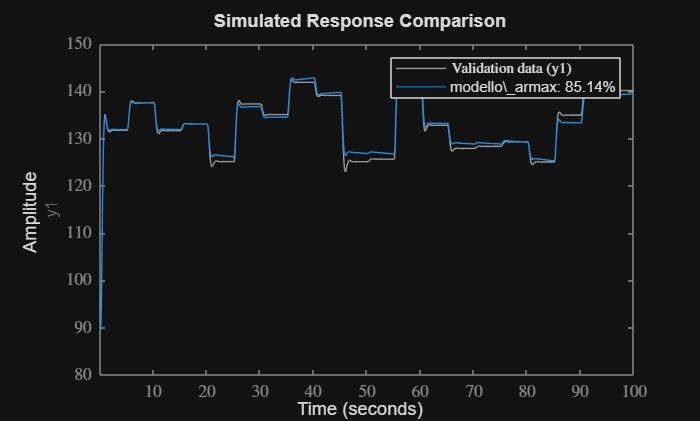


% Validazione con il primo set
y_val = y_1;
u_val = pw_1;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

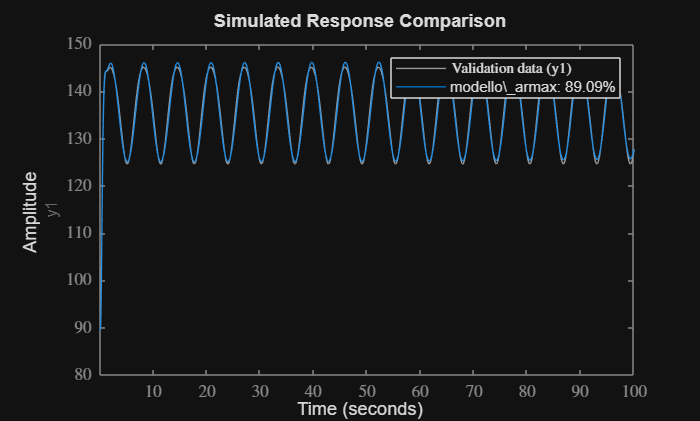

% Validazione con il secondo set
y_val = y_2;
u_val = pw_2;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

## Identificazione del modello utilizzando il segnale del quarto metodo

dividiamo in 70% e 30% per la validazione 

% 70% dei dati
n_70 = floor(N*0.7);
y_modello = y_4(1:n_70);
u_modello = pw_4(1:n_70);


data = iddata(y_modello , u_modello , Ts);

%definizione ordini AR MA X e K
n_ar = 5;
n_ma = 1;
n_x = 3;
k = 2;

%Sima del modello
modello_armax = armax(data , [n_ar n_x n_ma k])


modello_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                  
  A(z) = 1 - 3.41 z^-1 + 4.564 z^-2 - 3.015 z^-3 + 1.001 z^-4 - 0.1408 z^-5
                                                                           
  B(z) = 0.02115 z^-2 + 0.01164 z^-3 - 0.03266 z^-4                        
                                                                           
  C(z) = 1 + 0.6219 z^-1                                                   
                                                                           
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=3   nc=1   nk=2
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 99.97% (prediction focus)
FPE: 3.504e-06, MSE: 3.434e-06                   
 


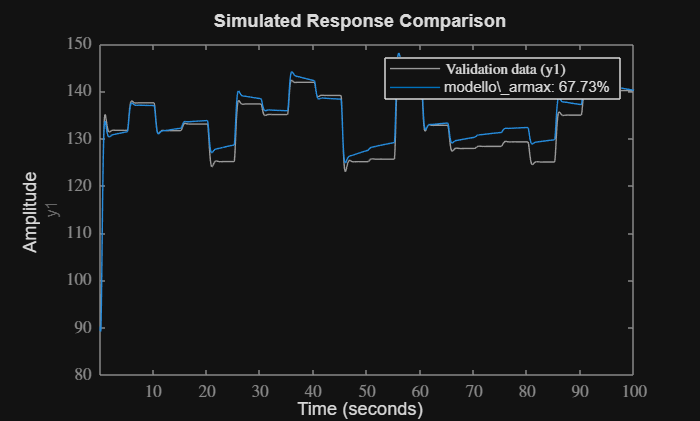

% Validazione con il 30% del quarto set
n_30 = N - n_70;

y_val = y_4(1:n_30);
u_val = pw_4(1:n_30);

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

% Validazione con il primo set
y_val = y_1;
u_val = pw_1;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

% Validazione con il secondo set
y_val = y_2;
u_val = pw_2;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax)

Il modello stimato con il primo set di dati (quello randomico) è il più preciso e meno complesso!